**Найти решение уравнения A[x] − λ x = y в виде ряда Фурье по собственным функциям симметричного дифференциального оператора A, действующего в одном из весовых пространств L²(a; b). Проиллюстрировать решение графически.**

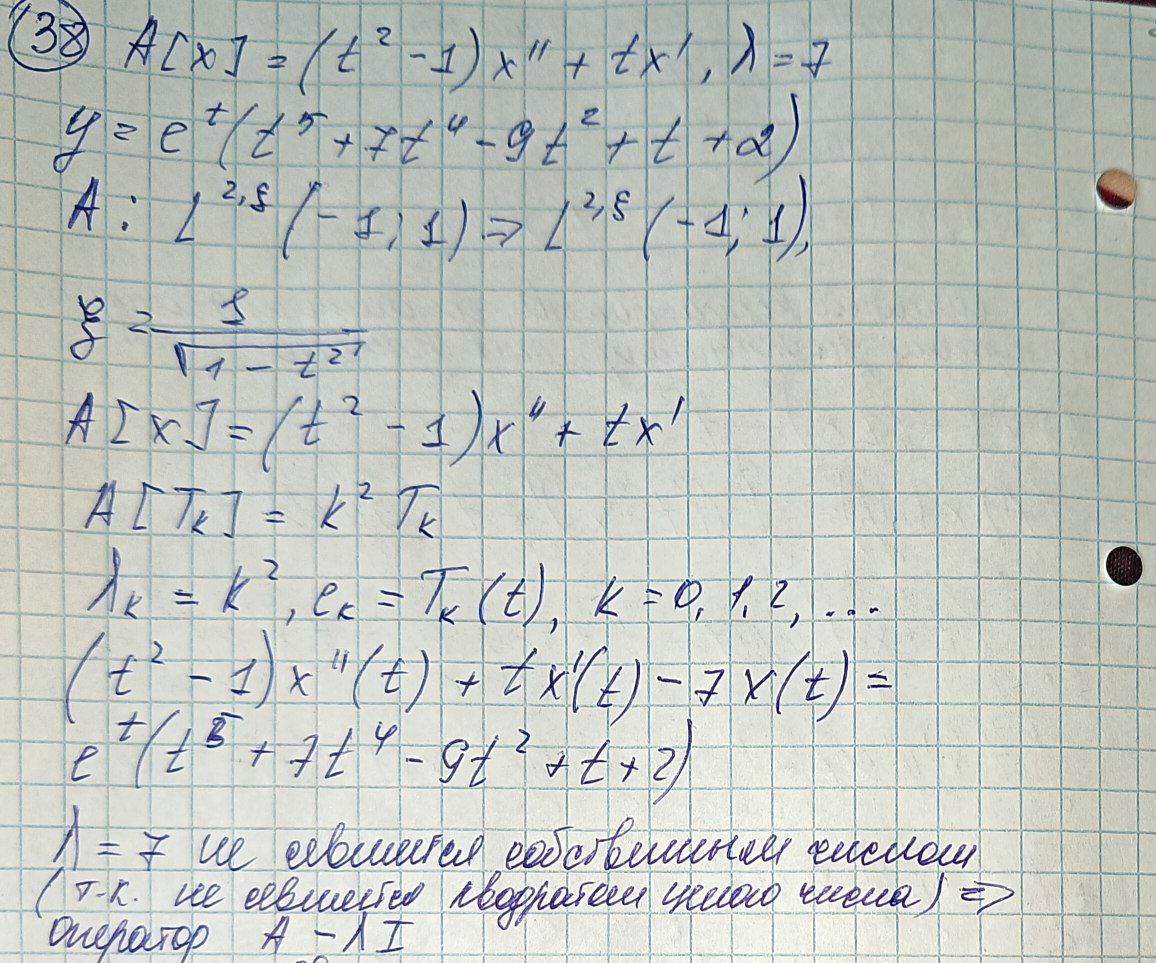

Параметры

N = 10;             
lambda = 7;
y = @(t)  exp(t).*(t.^5 + 7.*t.^4 - 9.*t.^2 + t + 2);

Собственные значения λ_k = k^2

norm_factor = sqrt(2 - ((0:N)' == 0)) / sqrt(pi);
k_vals = (0:N)';
lam_k = k_vals.^2;

Интегралы d_k = ∫_{-1}^1 [y(t) * T_k(t)]/√(1−t^2) dt

I = zeros(N+1,1);
for k = 0:N
    f = @(t) y(t).*chebyshevT(k, t) ./ sqrt(1 - t.^2);
    I(k+1) = integral(f, -1, 1, 'RelTol',1e-8,'AbsTol',1e-10,'Waypoints',[-1,0,1]);
end
d = norm_factor .* I;

Вычисляем c_k = d_k / (λ_k - λ)

c = zeros(N+1,1);
for k = 0:N
    c(k+1) = d(k+1) / (lam_k(k+1) - lambda);
end
tt = linspace(-1,1,100);%сетка для графиков

 Считаем e_k(tt)

Tk_tt = zeros(N+1, numel(tt));
for k = 0:N
    Tk_tt(k+1, :) = chebyshevT(k, tt);
end
e_tt = bsxfun(@times, Tk_tt, norm_factor);

x_N(t) = Σ c_k * e_k(t)

x_tt = c' * e_tt;

Графики

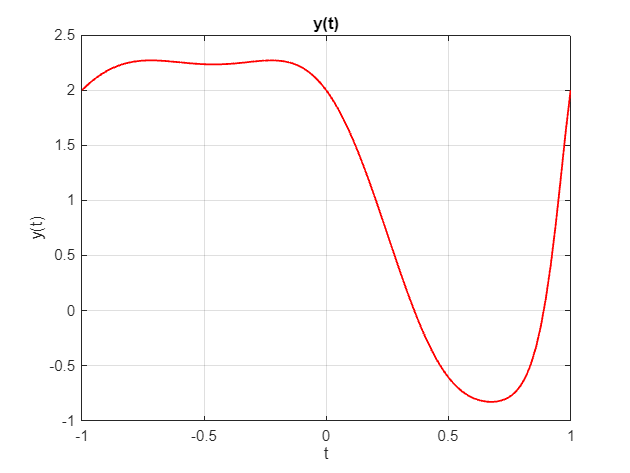

figure;
plot(tt, y(x_tt), 'r-', 'LineWidth', 1.2);
grid on;
title('y(t)');
xlabel('t'), ylabel('y(t)');

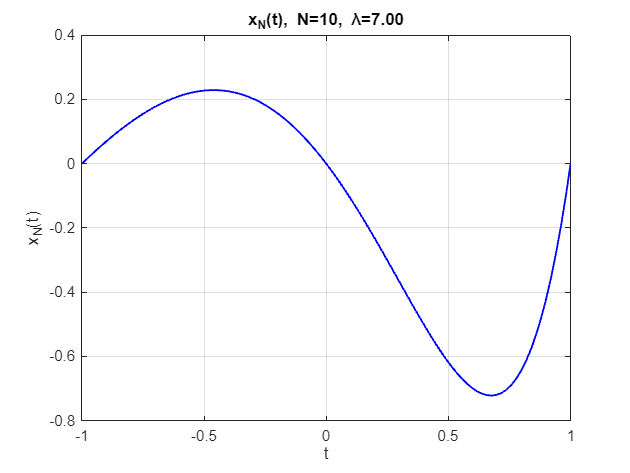

figure;
plot(tt, x_tt, 'b-', 'LineWidth', 1.2);
grid on;
title(sprintf('x_N(t), N=%d, λ=%.2f', N, lambda));
xlabel('t'), ylabel('x_N(t)');